close all
clc
clear all

## Parameters

fc = 300e6;                % Center frequency (Hz)
wirediameter = 12e-3;        % (m)
c = physconst('lightspeed'); % (m)
lambda = c / fc;             % (m)
Z0 = 50;                     % Input impedance (Ohm)
BW = 0.015 * fc;             % Bandwidth
fmin = fc - 2 * BW;          
fmax = fc + 2 * BW;
Nf = 101;
freq = linspace(fmin, fmax, Nf);

## Yagi-Uda Antenna

% Exciter
d = dipole;
d.Length = 0.98 * lambda / 2;
d.Width = cylinder2strip(wirediameter / 2);
d.Tilt = 90; % deg
d.TiltAxis = 'Y';

% Antenna
num_dirs = 5;
dirLength = 0.8 * ones(1, num_dirs);
refLength = 1.5;
refSpacing = 0.35;
dirSpacing = [0.2 0.2 0.25 0.3 0.3];
% initialdesign = [refLength refSpacing dirSpacing].*lambda;

yagidesign = yagiUda

yagidesign =   yagiUda with properties:

             Exciter: [1×1 dipoleFolded]
        NumDirectors: 3
      DirectorLength: 0.4080
     DirectorSpacing: 0.3400
     ReflectorLength: 0.5000
    ReflectorSpacing: 0.2500
                Tilt: 0
            TiltAxis: [1 0 0]
                Load: [1×1 lumpedElement]


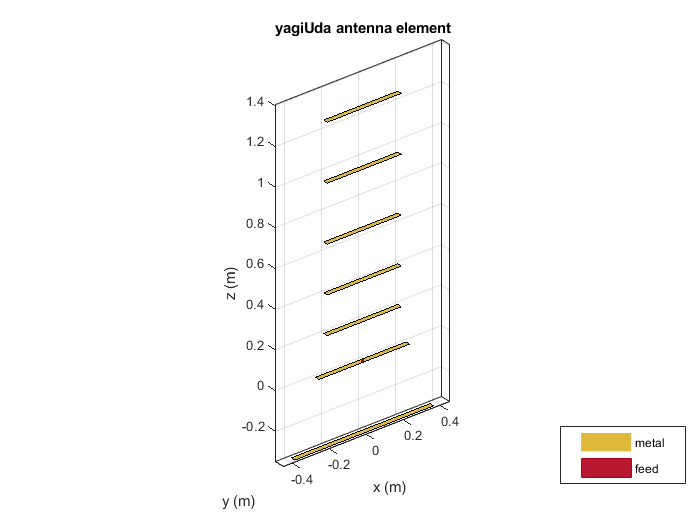

yagidesign.Exciter = d;
yagidesign.NumDirectors = num_dirs;
yagidesign.ReflectorLength = refLength * lambda / 2;
yagidesign.DirectorLength = dirLength * lambda / 2;
yagidesign.ReflectorSpacing = refSpacing * lambda;
yagidesign.DirectorSpacing = dirSpacing * lambda;
show(yagidesign)


% fig1 = figure;
% pattern(yagidesign,fc);

## Radiation Pattern Plot

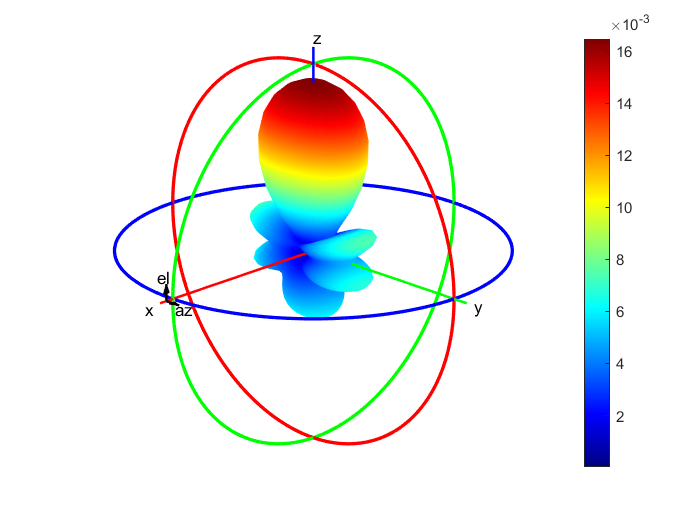

figure;
[efield, az, el] = pattern(yagidesign, fc, 'Type', 'efield');
phi = az';
theta = (90-el);
MagE = efield';
patternCustom(MagE, theta, phi)

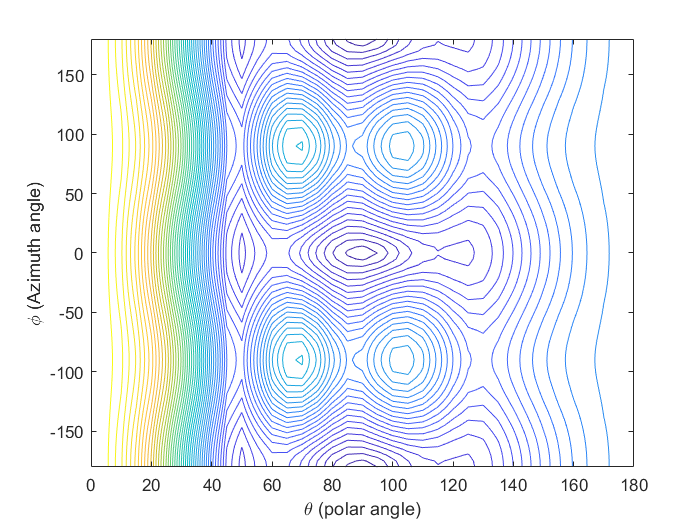

[X, Y] = meshgrid(theta, phi);

figure;
contour(X, Y, MagE, 50);
xlabel('\theta (polar angle)');
ylabel('\phi (Azimuth angle)');
axis([0, 180, -180, 180]);

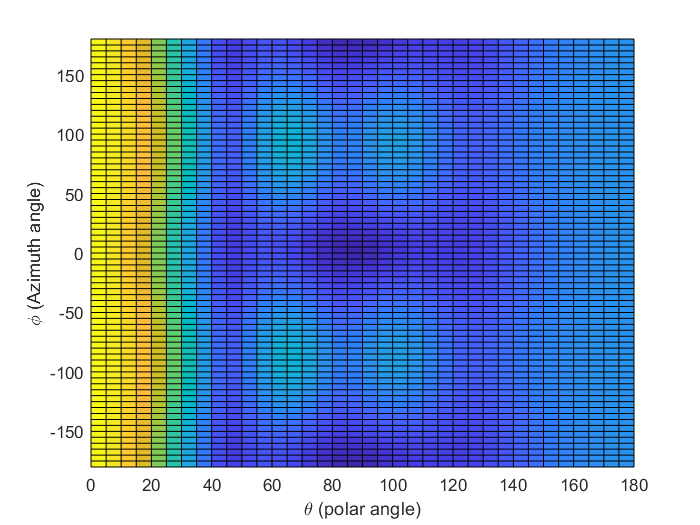


figure;
surf(X, Y, MagE);
xlabel('\theta (polar angle)');
ylabel('\phi (Azimuth angle)');
axis([0, 180, -180, 180]);
view(2)

drawnow

## E- / H- Plane Cut

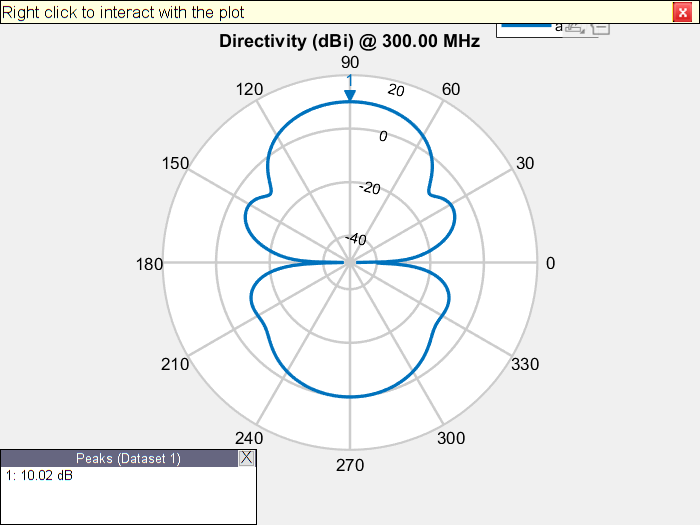

% E-plane
figure;
patternElevation(yagidesign, fc, 0, 'Elevation', 0:1:359);

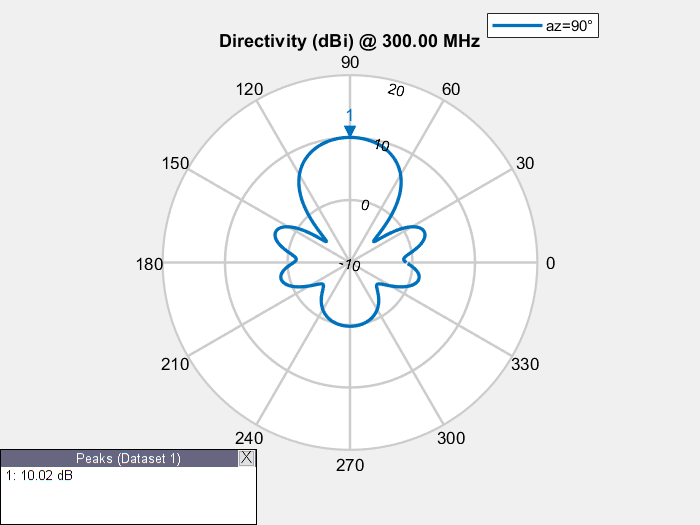

pE = polarpattern('gco');

% H-plane
figure;
patternElevation(yagidesign, fc, 90, 'Elevation', 0:1:359);

pH = polarpattern('gco');


## Input reflection Coefficient

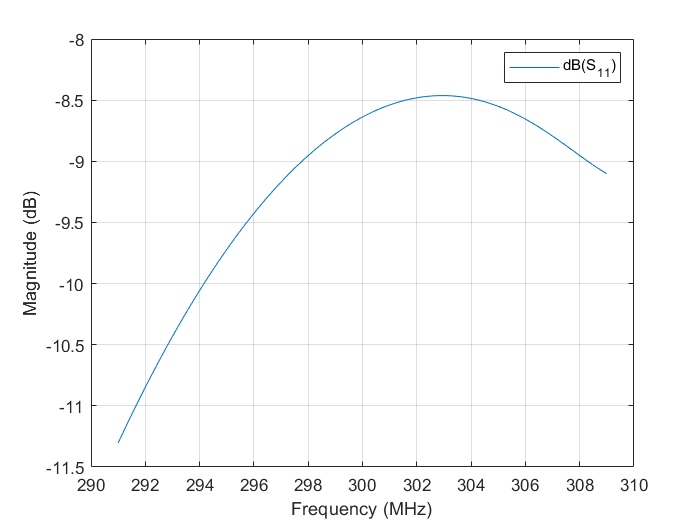

s = sparameters(yagidesign, freq, Z0);
fig5 = figure;
rfplot(s);

## Data Processing

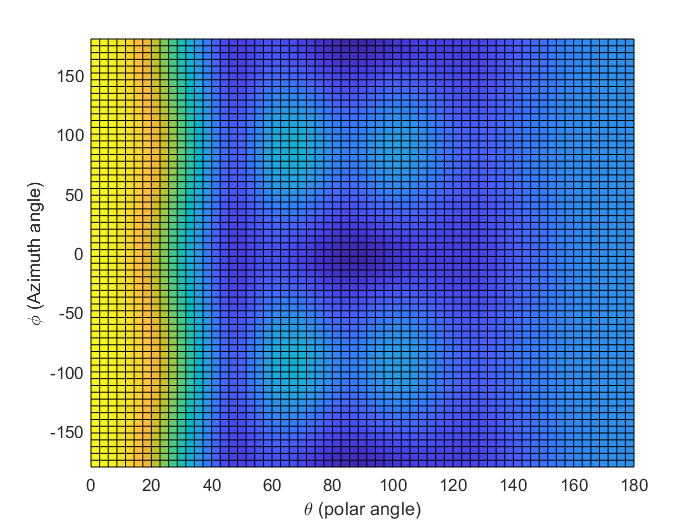

% Resize MagE(73, 37) to MagE_(64, 64)
out_size = [64, 64];
MagE_ = imresize(MagE, out_size);

% Plot MagE_
[X_, Y_] = meshgrid(linspace(180, 0, out_size(1)), ...
                    linspace(180, -180, out_size(2)));

figure;
surf(X_, Y_, MagE_);
xlabel('\theta (polar angle)');
ylabel('\phi (Azimuth angle)');
axis([0, 180, -180, 180]);
view(2)

drawnow
     

% Write data as .dat file
dir_ = 'D:\Research_USA\matlab_project\YagiUda\Data\';
ind = '1';
dir1 = strcat(dir_, num2str(ind), '.dat');
dlmwrite(dir1, MagE_, 'delimiter', ' ', 'precision', '%.4e');
